## REDO exercise of 15-04

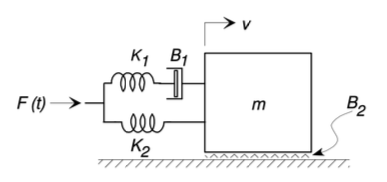

clear variables
close all

% definition of symbolic variables
syms t v_m(t) v_S1(t) v_S2(t) v_D1(t) v_D2(t) v_F(t) 
syms F_m(t) F_S1(t) F_S2(t) F_D1(t) F_D2(t) F_F(t)
% define vector 
%syms alpha tau
% definition of vetcor of through variables
tau = [ 
  F_m(t) 
  F_D1(t)
  F_S1(t)
  F_D2(t)
  F_S2(t)
  F_F(t)
]

$$tau = \left(\begin{array}{c} F_{m}\left(t\right)\\ F_{\mathrm{D1}}\left(t\right)\\ F_{\mathrm{S1}}\left(t\right)\\ F_{\mathrm{D2}}\left(t\right)\\ F_{\mathrm{S2}}\left(t\right)\\ F_{F}\left(t\right) \end{array}\right)$$

% definition of vector of across variables
alpha = [ 
  v_m(t) 
  v_D1(t)
  v_S1(t)
  v_D2(t)
  v_S2(t)
  v_F(t)
]

$$alpha = \left(\begin{array}{c} v_{m}\left(t\right)\\ v_{\mathrm{D1}}\left(t\right)\\ v_{\mathrm{S1}}\left(t\right)\\ v_{\mathrm{D2}}\left(t\right)\\ v_{\mathrm{S2}}\left(t\right)\\ v_{F}\left(t\right) \end{array}\right)$$


% definition of problem dimensions
ne = 6; % number of elements
nb = 3; % number of branches
nc = ne-nb; % number of chords/links

Incidence matrix

syms IM;
IM = [0, 0, -1, 0, -1, 1;
      0, -1, 1, 0, 0, 0;
      -1, 1, 0, -1, 1, 0;
      1, 0, 0, 0, 1, -1]

IM =      0     0    -1     0    -1     1
     0    -1     1     0     0     0
    -1     1     0    -1     1     0
     1     0     0     0     1    -1



% define it as symbolic
IMs = sym(IM);
IMr = IMs(1:nc, 1:ne);

% Finding echelon form -> Af
Af = rref(IMr)

$$Af = \left(\begin{array}{cccccc} 1 & 0 & 0 & 1 & 0 & -1\\ 0 & 1 & 0 & 0 & 1 & -1\\ 0 & 0 & 1 & 0 & 1 & -1 \end{array}\right)$$

Equations for primary and secondary through variables

Ib = Af(1:nb, 1:nb)

$$Ib = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

Ac = Af(1:nb, nb+1:ne)

$$Ac = \left(\begin{array}{ccc} 1 & 0 & -1\\ 0 & 1 & -1\\ 0 & 1 & -1 \end{array}\right)$$

#### Node equations

node_eqns = tau(1:nb) == -Ac*tau(nb+1:ne)

$$node\_eqns = \left(\begin{array}{c} F_{m}\left(t\right)=F_{F}\left(t\right)-F_{\mathrm{D2}}\left(t\right)\\ F_{\mathrm{D1}}\left(t\right)=F_{F}\left(t\right)-F_{\mathrm{S2}}\left(t\right)\\ F_{\mathrm{S1}}\left(t\right)=F_{F}\left(t\right)-F_{\mathrm{S2}}\left(t\right) \end{array}\right)$$

#### Loop equations

Bf = null(Af)'

$$Bf = \left(\begin{array}{cccccc} -1 & 0 & 0 & 1 & 0 & 0\\ 0 & -1 & -1 & 0 & 1 & 0\\ 1 & 1 & 1 & 0 & 0 & 1 \end{array}\right)$$

Af*Bf'  % <--- check conservation of energy

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Bb = -Ac'

$$Bb = \left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & -1 & -1\\ 1 & 1 & 1 \end{array}\right)$$

loop_eqns = alpha(nb+1:ne) == -Bb*alpha(1:nb)

$$loop\_eqns = \left(\begin{array}{c} v_{\mathrm{D2}}\left(t\right)=v_{m}\left(t\right)\\ v_{\mathrm{S2}}\left(t\right)=v_{\mathrm{D1}}\left(t\right)+v_{\mathrm{S1}}\left(t\right)\\ v_{F}\left(t\right)=-v_{\mathrm{D1}}\left(t\right)-v_{\mathrm{S1}}\left(t\right)-v_{m}\left(t\right) \end{array}\right)$$